# **Retrieval Model and Eigenvalue Analysis Data**

### Model Data

First, instantiate the OpenSeesMatlab interface class. This class provides native OpenSees commands, as well as additional visualization, pre/post-processing, and utility methods.

opsMAT = OpenSeesMatlab();
ops = opsMAT.opensees;

For example, the `tool` property provides a function `loadExamples` to run some built-in models. Of course, you can run your own model; the built-in model is used here for demonstration purposes only.

opsMAT.utils.loadExamples("Frame3D");
% or your model here

We can visualize the model using the `plotModel` function in the `vis` attribute.

[OpenSeesMatlab] Model summary
  Nodes: 384
  Beam elements: 930


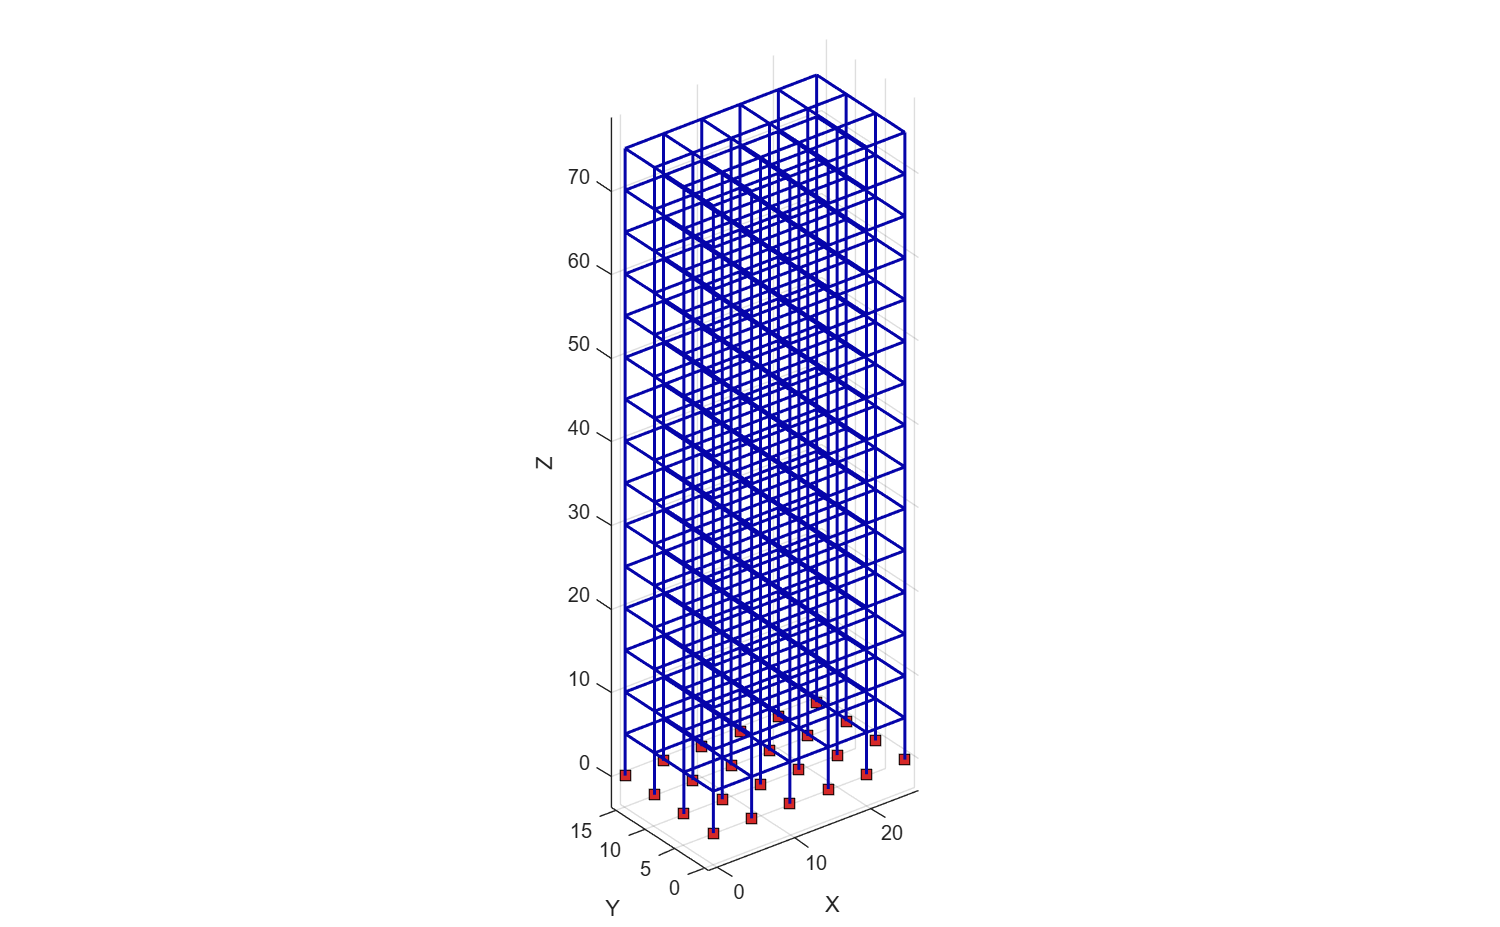

figure;
h = opsMAT.vis.plotModel();

We can retrieve data from the current model, which returns a nested `struct`. You can view the data using MATLAB's workspace variables.

modelData = opsMAT.post.getModelData();
disp(modelData)

           Nodes: [1×1 struct]
           Fixed: [1×1 struct]
    MPConstraint: [1×1 struct]
           Loads: [1×1 struct]
        Elements: [1×1 struct]
         NumNode: 384
      NumElement: 930



Finally, we can print the information for each field.

S = modelData;

stack = {{'S', S}};

while ~isempty(stack)
    item = stack{end};
    stack(end) = [];

    name = item{1};
    val  = item{2};

    if isstruct(val)
        fns = fieldnames(val);
        for i = numel(fns):-1:1
            f = fns{i};
            stack{end+1} = {sprintf('%s.%s', name, f), val.(f)};
        end
    else
        sz = strjoin(string(size(val)), 'x');
        fprintf('%s : %s\n', name, sz);
    end
end

S.Nodes.Tags : 384x1
S.Nodes.Coords : 384x3
S.Nodes.Ndm : 384x1
S.Nodes.Ndf : 384x1
S.Nodes.UnusedTags : 0x1
S.Nodes.Bounds : 1x6
S.Nodes.MinBoundSize : 1x1
S.Nodes.MaxBoundSize : 1x1
S.Fixed.NodeTags : 24x1
S.Fixed.NodeIndex : 24x1
S.Fixed.Coords : 24x3
S.Fixed.Dofs : 24x6
S.MPConstraint.PairNodeTags : 0x2
S.MPConstraint.Cells : 0x3
S.MPConstraint.MidCoords : 0x3
S.MPConstraint.Dofs : 0x6
S.Loads.PatternTags : 0x1
S.Loads.Node.PatternNodeTags : 0x2
S.Loads.Node.Values : 0x3
S.Loads.Element.Beam.PatternElementTags : 0x2
S.Loads.Element.Beam.Values : 0x10
S.Loads.Element.Surface.PatternElementTags : 0x2
S.Loads.Element.Surface.Values : 0x0
S.Elements.Summary.Tags : 930x1
S.Elements.Summary.ClassTags : 930x1
S.Elements.Summary.CenterCoords : 930x3
S.Elements.Families.Truss.Tags : 0x1
S.Elements.Families.Truss.Cells : 0x3
S.Elements.Families.Beam.Tags : 930x1
S.Elements.Families.Beam.Cells : 930x3
S.Elements.Families.Beam.Midpoints : 930x3
S.Elements.Families.Beam.Lengths : 930x1
S.Elemen

### Eigen Data

First, we need to save the eigenvalue analysis results data for future reuse.

tag = 1;
opsMAT.post.saveEigenData(tag, 10, solver='-genBandArpack');

[OpenSees] Using DomainModalProperties - Developed by: Massimo Petracca, Guido Camata, ASDEA Software Technology


Then, data is retrieved from the file, returning a nested `structure` that stores the various results of the eigenvalue analysis.

eigenData = opsMAT.post.getEigenData(odbTag=tag);
disp(eigenData)

                EigenVectors: [1×1 struct]
    InterpolatedEigenVectors: [1×1 struct]
                  ModalProps: [1×1 struct]
                   ModelInfo: [1×1 struct]
                    ModeTags: [10×1 double]



Using this data, we can visualize the first modal shapes.

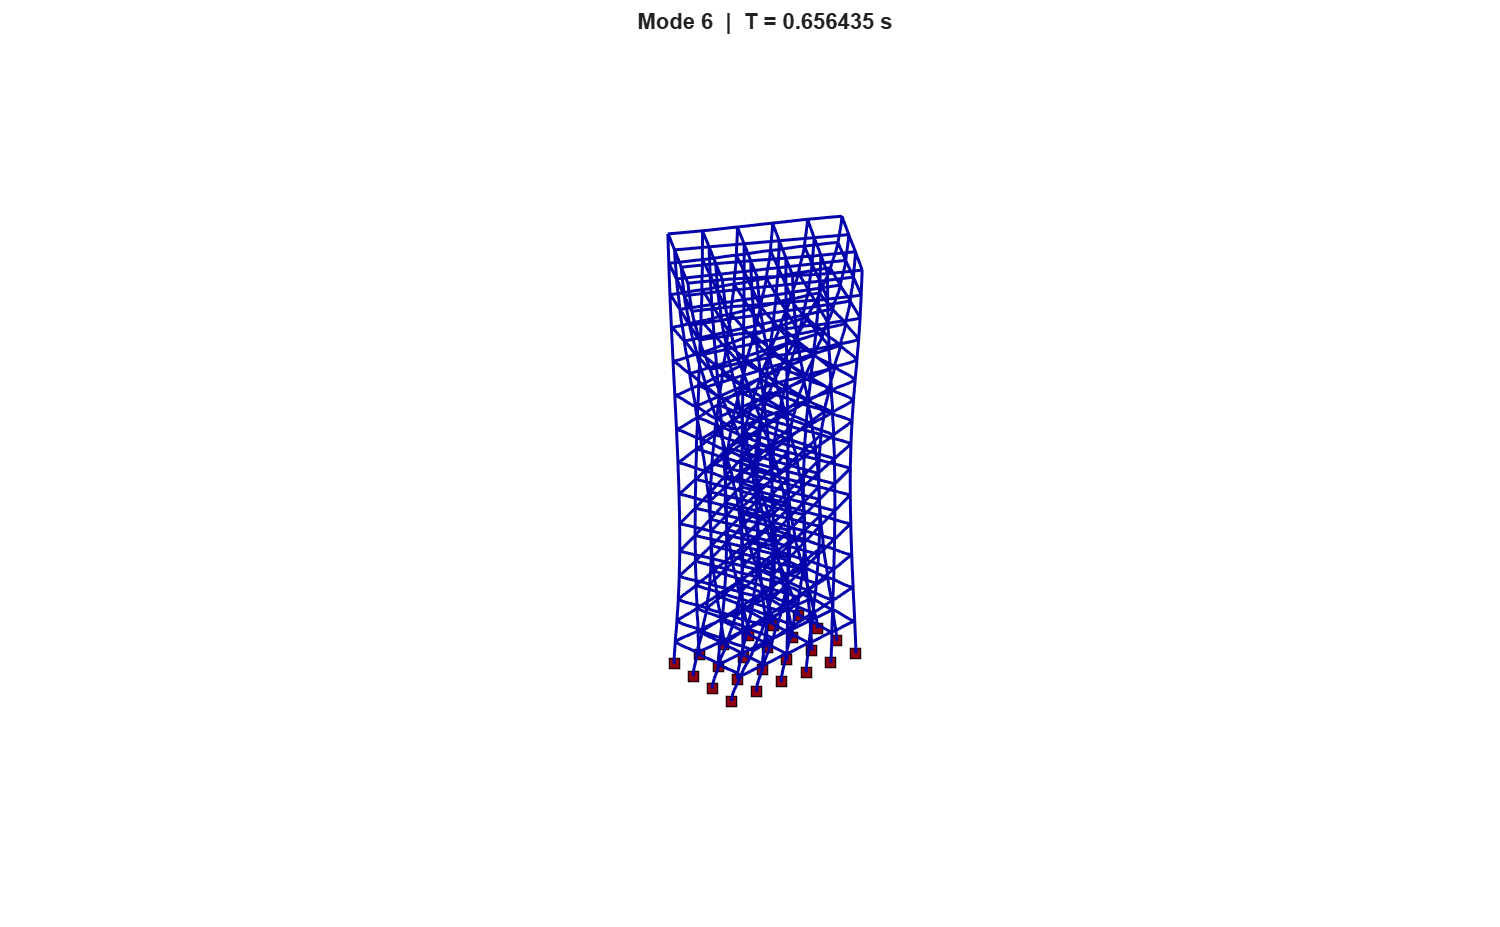

figure;
opsMAT.vis.plotEigen(6, eigenData);
axis off

S = eigenData;

stack = {{'S', S}};

while ~isempty(stack)
    item = stack{end};
    stack(end) = [];

    name = item{1};
    val  = item{2};

    if isstruct(val)
        fns = fieldnames(val);
        for i = numel(fns):-1:1
            f = fns{i};
            stack{end+1} = {sprintf('%s.%s', name, f), val.(f)};
        end
    else
        sz = strjoin(string(size(val)), 'x');
        fprintf('%s : %s\n', name, sz);
    end
end

S.EigenVectors.data : 10x384x6
S.EigenVectors.nodeCoords : 384x3
S.EigenVectors.nodeNdf : 384x1
S.EigenVectors.nodeNdm : 384x1
S.EigenVectors.nodeTags : 384x1
S.InterpolatedEigenVectors.cellNodeTags : 930x2
S.InterpolatedEigenVectors.cells : 4650x3
S.InterpolatedEigenVectors.data : 10x5580x3
S.InterpolatedEigenVectors.eleTags : 930x1
S.InterpolatedEigenVectors.modeTags : 10x1
S.InterpolatedEigenVectors.nodeTags : 384x1
S.InterpolatedEigenVectors.nptsPerElement : 1x1
S.InterpolatedEigenVectors.pointID : 5580x1
S.InterpolatedEigenVectors.points : 5580x3
S.ModalProps.attrs.centerOfMass : 1x3
S.ModalProps.attrs.domainSize : 1x1
S.ModalProps.attrs.totalFreeMass : 1x6
S.ModalProps.attrs.totalMass : 1x6
S.ModalProps.raw.centerOfMass : 1x3
S.ModalProps.raw.domainSize : 1x1
S.ModalProps.raw.eigenFrequency : 1x10
S.ModalProps.raw.eigenLambda : 1x10
S.ModalProps.raw.eigenOmega : 1x10
S.ModalProps.raw.eigenPeriod : 1x10
S.ModalProps.raw.partiFactorMX : 1x10
S.ModalProps.raw.partiFactorMY : 1x10
S.

Let's look at the period of each mode.

S.ModalProps.raw.eigenPeriod

ans =     2.2607    2.1196    1.9810    0.7388    0.6988    0.6564    0.4202    0.4051    0.3870    0.2951


Let's look at the **cumulative participation mass ratio (%)** in each direction.

S.ModalProps.raw.partiMassRatiosCumuMX

ans =     0.0000   80.7272   80.7272   80.7272   91.1228   91.1228   91.1228   94.5874   94.5874   94.5874


S.ModalProps.raw.partiMassRatiosCumuMY

ans =    79.6341   79.6341   79.6341   90.9131   90.9131   90.9131   94.4481   94.4481   94.4481   96.2749


S.ModalProps.raw.partiMassRatiosCumuMZ

ans = 1.0e-28 *

    0.0000    0.0005    0.0010    0.0572    0.1063    0.1226    0.3151    0.3305    0.3471    0.4768


S.ModalProps.raw.partiMassRatiosCumuRMX

ans =    19.1567   19.1567   19.1567   71.8213   71.8213   71.8213   78.3219   78.3219   78.3219   85.4282


S.ModalProps.raw.partiMassRatiosCumuRMY

ans =     0.0000   16.7152   16.7152   16.7152   67.3875   67.3875   67.3875   72.9309   72.9309   72.9309


S.ModalProps.raw.partiMassRatiosCumuRMZ

ans =     0.0000    0.0000   81.5449   81.5449   81.5449   91.1897   91.1897   91.1897   94.6036   94.6036
